clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

% IMU parameters
ref_grav    = 9.81;                 % reference gravity  in [m/s2]
ref_omeg    = 1;                    % MEMS reference rotation in [rad/s]

%% call simulation function to 'simulate' and collect the data
f_imu           = 10;             % IMU sample rate in [Hz]
t               = 0:1/f_imu:90;   % considered time span for training data; here 900 s
num_train_seq   = 1;              % number of IMU data training sequences
simulation      = MAIN_SIM(t, f_imu, ref_grav, ref_omeg, num_train_seq);

%% collected data from simulation
%% gyroscope values
g_xup     = simulation.g_xup;

%% accelerometer values
a_zup     = simulation.acc_zup;

%% Deterministic and Stochastic errors
bias_gyro           = simulation.bias_gyro;
bias_acc            = simulation.bias_acc;
SF_gyro             = simulation.SF_gyro;
SF_acc              = simulation.SF_acc;
VRW                 = simulation.VRW;
ARW                 = simulation.ARW;

% % Split the data into training and testing sets
split_ratio             = 0.8; % 80% training, 20% testing
num_samples             = size(a_zup, 1);
split_idx_train         = round(split_ratio * num_samples);
split_idx_val           = round(0.8 * num_samples);

%% Expand reference data 'labels' to be same size as the training & change to cell
labels_omeg         = repelem(ref_omeg,num_samples,num_train_seq);
labels_grav         = repelem(ref_grav,num_samples,num_train_seq);

%% split the data to training, validation and testing, including the reference data
%% Training sets
train_data_gyr      = num2cell(g_xup(1:split_idx_train, :),1);
train_data_acc      = num2cell(a_zup(1:split_idx_train, :),1);
train_labels_omeg   = num2cell(labels_omeg(1:split_idx_train, :),1);
train_labels_grav   = num2cell(labels_grav(1:split_idx_train, :),1);

%% Testing sets
test_data_gyr       = num2cell(g_xup(split_idx_val+1:end, :),1);
test_data_acc       = num2cell(a_zup(split_idx_val+1:end, :),1);
test_labels_omeg    = num2cell(labels_omeg(split_idx_val+1:end, :),1);
test_labels_grav    = num2cell(labels_grav(split_idx_val+1:end, :),1);

%% since I need my input size to the NN to be 1, I need to change the
%% appearance of the cell array, where each cell of both data & labels
%% to be 1xsplit_idx & 1xsplit_id+1:end respectively

for k = 1:num_train_seq
    train_data_gyr{k}       = train_data_gyr{k}';
    train_data_acc{k}       = train_data_acc{k}';
    train_labels_omeg{k}    = train_labels_omeg{k}';
    train_labels_grav{k}    = train_labels_grav{k}';
        
    test_data_gyr{k}        = test_data_gyr{k}';
    test_data_acc{k}        = test_data_acc{k}';
    test_labels_omeg{k}     = test_labels_omeg{k}';
    test_labels_grav{k}     = test_labels_grav{k}';
end

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:08 |         0.97 |          0.5 |          0.0010 |
|       1 |          50 |       00:00:10 |         0.21 |      2.2e-02 |          0.0010 |
|       1 |         100 |       00:00:11 |         0.16 |      1.3e-02 |          0.0010 |
|       1 |         150 |       00:00:12 |         0.13 |      8.0e-03 |          0.0010 |
|       1 |         200 |       00:00:12 |         0.13 |      8.7e-03 |          0.0010 |
|       1 |         250 |       00:00:13 |         0.09 |      4.4e-03 |          0.0010 |
|       1 |         300 |       00:00:14 |         0.05 |      1.5

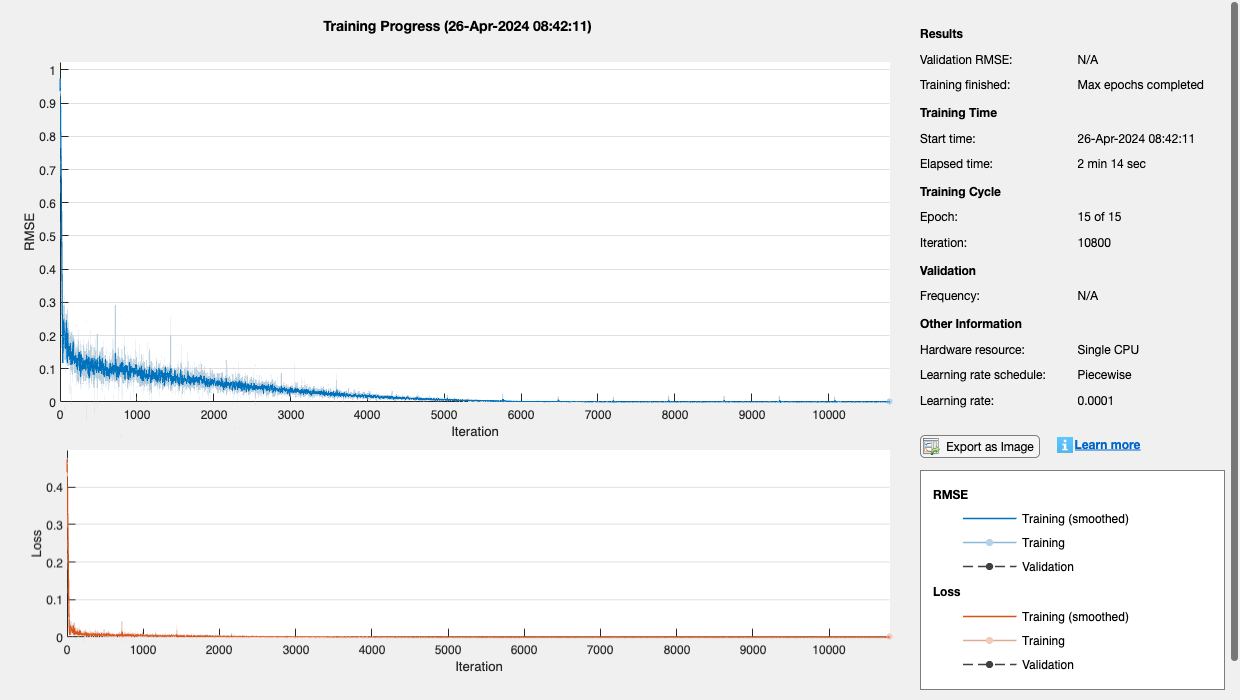

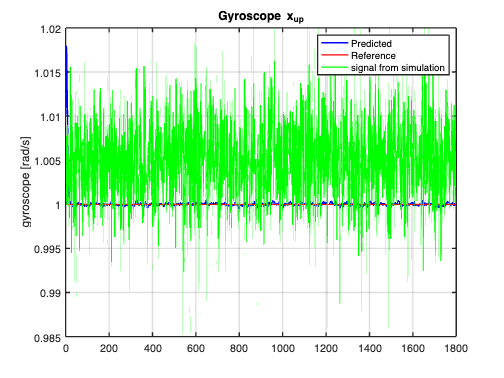

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         9.61 |         46.2 |          0.0010 |
|       1 |          50 |       00:00:04 |         8.04 |         32.3 |          0.0010 |
|       1 |         100 |       00:00:04 |         6.77 |         22.9 |          0.0010 |
|       1 |         150 |       00:00:05 |         5.33 |         14.2 |          0.0010 |
|       1 |         200 |       00:00:06 |         3.63 |          6.6 |          0.0010 |
|       1 |         250 |       00:00:07 |         2.42 |          2.9 |          0.0010 |
|       1 |         300 |       00:00:08 |         1.61 |         

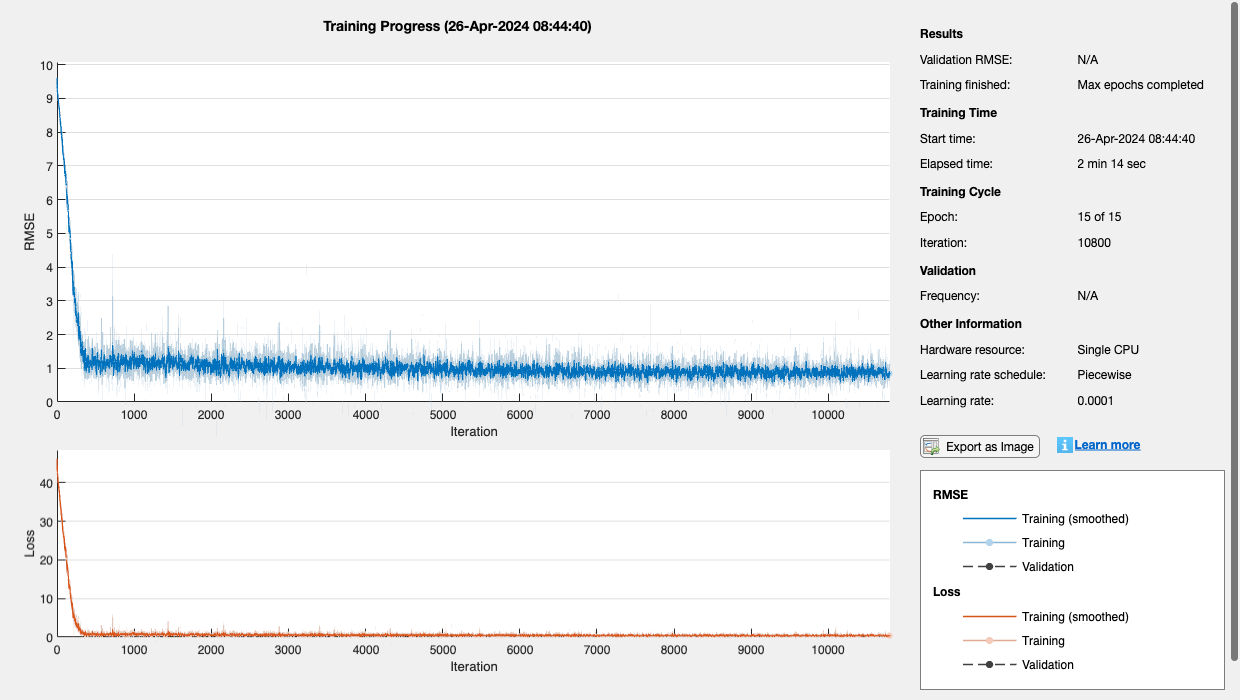

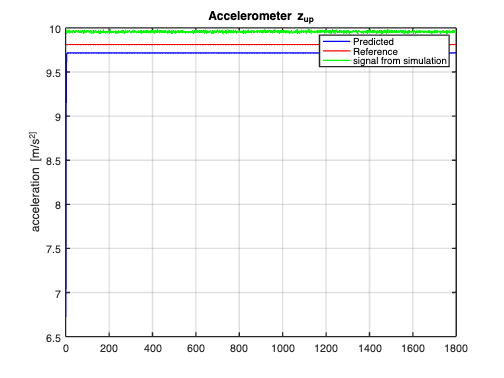

%% Running individual sensors into the NN
for j = 1:2
    if j == 1       % gyroscope data
        train_data     = train_data_gyr;
        train_labels   = train_labels_omeg;

        test_data      = test_data_gyr;
        test_labels    = test_labels_omeg;

        % configure neural network (NN)
        numFeatures     = size(train_data, 1); % Number of features in your data
        numHiddenUnits  = 16; % Adjust as needed
        numResponses    = 1;

        layers = [
            sequenceInputLayer(numFeatures)
            lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
            dropoutLayer(0.2)
            fullyConnectedLayer(numResponses)
            regressionLayer 
        ];

        % Set training options with the Adam optimizer
        options = trainingOptions('adam', ...
            'MaxEpochs', 15, ...
            'MiniBatchSize', 2^5, ...
            'SequenceLength', 10, ... % Adjust as needed
            'GradientThreshold', 1, ...
            'InitialLearnRate', 0.001, ...
            'LearnRateSchedule', 'piecewise', ...
            'Shuffle', 'every-epoch', ...  % to reduce biases in training
            'ExecutionEnvironment', 'auto', ...
            'Plots','training-progress',...
            'Verbose',1);

        % Train the LSTM network
        net = trainNetwork(train_data, train_labels, layers, options);

        % Test the trained network
        predicted_labels = predict(net, test_data);
        predicted_labels = predicted_labels';
    
        % plot for gyroscope
        aa_g = g_xup(split_idx_train+1:end,1);
        aa_g = aa_g';
        fig2=figure;
        plot(predicted_labels{:,1},'b');
        hold on;
        plot(test_labels{:,1}, 'r');
        plot(aa_g,'g');
        grid on
        xlabel('time [s]');
        ylabel('gyroscope [rad/s]');
        legend('Predicted','Reference','signal from simulation');
        title('Gyroscope x_u_p');
        exportgraphics(fig2,'Gyroscope x_u_p.png','Resolution',300);

    else            % accelerometer data
        train_data     = train_data_acc;
        train_labels   = train_labels_grav;


        test_data      = test_data_acc;
        test_labels    = test_labels_grav;

        % configure neural network (NN)
        numFeatures     = size(train_data, 1); % Number of features in your data
        numHiddenUnits  = 16; % Adjust as needed
        numResponses    = 1;

        layers = [
            sequenceInputLayer(numFeatures)
            lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
            dropoutLayer(0.2)
            fullyConnectedLayer(numResponses)
            regressionLayer 
        ];

        % Set training options with the Adam optimizer
        options = trainingOptions('adam', ...
            'MaxEpochs', 15, ...
            'MiniBatchSize', 2^5, ...
            'SequenceLength', 10, ... % Adjust as needed
            'GradientThreshold', 1, ...
            'InitialLearnRate', 0.001, ...
            'LearnRateSchedule', 'piecewise', ...
            'Shuffle', 'every-epoch', ...  % to reduce biases in training
            'ExecutionEnvironment', 'auto', ...
            'Plots','training-progress',...
            'Verbose',1);

        % Train the LSTM network
        net = trainNetwork(train_data, train_labels, layers, options);

        % Test the trained network
        predicted_labels = predict(net, test_data);
        predicted_labels = predicted_labels';

        % plot for accelerometer
        aa_a = a_zup(split_idx_train+1:end,1);
        aa_a = aa_a';
        fig1=figure;
        plot(predicted_labels{:,1},'b');
        hold on;
        plot(test_labels{:,1}, 'r');
        plot(aa_a,'g');
        grid on
        xlabel('time [s]');
        ylabel('acceleration [m/s^2]');
        legend('Predicted','Reference','signal from simulation');
        title('Accelerometer z_u_p');
        exportgraphics(fig1,'Accelerometer z_u_p.png','Resolution',300);
    end
end